clear all
clc
close all

%% Import Experimental data %%
load('Experiment_EColi_Amp.mat');
xdata =time;
ydata =N;
error =err;


%% nlinfit paramter estimation %%
opts = statset('Display','iter','TolFun',1e-18, 'TolX', 1e-18, 'MaxIter',10000, 'MaxFunEvals', 10000, 'DerivStep',10^-14);

K0 = [-4 0.0008 -.5 .06 0.000001 8.0]; % intial guess
[K,R,J,CovB,MSE,ErrorModelInfo] = nlinfit(xdata, ydata, @f_model_eval, K0,'Options', opts);

 
                                     Norm of         Norm of
   Iteration             SSE        Gradient           Step 
  -----------------------------------------------------------
           0         21.6757
           1         12.0758     1.07246e+06        0.691493
           2          11.018     9.36298e+06        0.412848
           3         10.4381          436287        0.128063
           4         10.4173          554156       0.0769211
           5         10.3975          236753       0.0301407
           6         10.3948          121053       0.0217279
           7         10.3936          118730       0.0219817
           8         10.3924         11312.4      0.00298914
           9         10.3922         12930.9      0.00415487
          10         10.3922          124807     0.000344616
          11         10.3922          183944     4.69793e-15
          12         10.3922         49530.7     5.28547e-15
Iterations terminated: relative change in SSE less th

K' % estimated parameters

ans =    -3.8498
   -0.0022
   -0.1570
    1.1598
    0.0000
    7.8015


%% Confidence intervals%
ci = nlparci(K,R,'jacobian',J,'alpha',0.32)

ci =    -4.2694   -3.4302
   -0.0170    0.0126
   -0.3962    0.0822
    0.7652    1.5545
   -0.0000    0.0000
    7.3615    8.2414



delta_param = abs(ci(:,1)-K') % abosolute +/- range

delta_param =     0.4196
    0.0148
    0.2392
    0.3946
    0.0000
    0.4399


%% Confidence band calculations %%

xrange = [linspace(0,13, 100), linspace(0,3, 20), linspace(3,5, 20), linspace(5,8, 20), linspace(8,10, 20),linspace(10,13, 20)];

[Ypred,delta] = nlpredci(@(K, xdata)f_model_eval(K, xdata),xrange,K,R,'Jacobian',J, 'alpha',.05);
L_c = -delta(1:100,1)+Ypred(1:100,1);
H_c = +delta(1:100,1)+Ypred(1:100,1);
L_p = -delta(101:200,1)+Ypred(101:200,1);
H_p = +delta(101:200,1)+Ypred(101:200,1);

%% Plots
set(groot,'defaultfigureposition',[150 150 380 350])

A_on = [K(1), 0; (K(2)^2), K(3)]

A_on =    -3.8498         0
    0.0000   -0.1570


A_off = [1.354, K(4); 0, -K(4)]

A_off =     1.3540    1.1598
         0   -1.1598


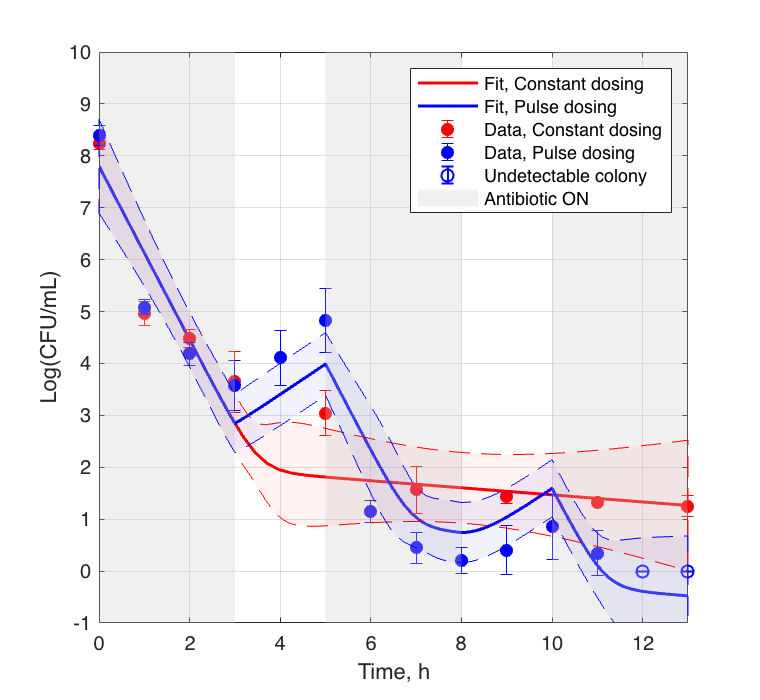


f0 = K(5);
N0 = K(6);
x0 = 10.^N0*[(1-f0), f0];
tc = linspace(0, 13, 50);
tspan1 = linspace(0, 3, 20);
tspan2 = linspace(3, 5, 20);
tspan3 = linspace(5, 8, 20);
tspan4 = linspace(8, 10, 20);
tspan5 = linspace(10, 13, 20);

yc = ExponentialM(A_on, tc, x0);
y1 = ExponentialM(A_on, tspan1, x0);
y2 = ExponentialM(A_off, tspan2, [y1(end,1), y1(end,2)]);
y3 = ExponentialM(A_on, tspan3, [y2(end,1), y2(end,2)]);
y4 = ExponentialM(A_off, tspan4, [y3(end,1), y3(end,2)]);
y5 = ExponentialM(A_on, tspan5, [y4(end,1), y4(end,2)]);


yp = [log10(sum(y1,2)); log10(sum(y2,2)) ; log10(sum(y3,2)); log10(sum(y4,2)); log10(sum(y5,2))];
y_n = [log10(y1(:,1)); log10(y2(:,1));log10(y3(:,1));log10(y4(:,1));log10(y5(:,1))];
y_p = [log10(y1(:,2)); log10(y2(:,2));log10(y3(:,2));log10(y4(:,2));log10(y5(:,2))];
tp = [tspan1'; tspan2'; tspan3'; tspan4'; tspan5'];
% plots

plot(tc, log10(sum(yc,2)), 'r-', 'MarkerFaceColor', 'r', 'LineWidth', 1.5)
hold on 
plot(tp, yp, 'b-', 'MarkerFaceColor', 'b', 'LineWidth', 1.5)
hold on
errorbar(xdata(1:9,1),ydata(1:9,1),error(1:9,1), 'ro', 'MarkerFaceColor','r')
hold on
errorbar(xdata(10:21,1),ydata(10:21,1), error(10:21,1),'bo', 'MarkerFaceColor', 'b')
hold on

errorbar(xdata(22:23,1),ydata(22:23,1), error(22:23,1), 'bo','LineWidth', 1.0);

x1 = [0 3 3 0];
y1 = [-2 -2 10 10];
x2 = [5 8 8 5];
y2 = [-2 -2 10 10];
x3 = [10 13 13 10];
y3 = [-2 -2 10 10];
patch(x1,y1, [0.8 0.8 0.8], 'LineStyle', 'none', 'FaceAlpha', 0.3);
patch(x2,y2, [0.8 0.8 0.8], 'LineStyle', 'none', 'FaceAlpha', 0.3);
patch(x3, y3, [0.8 0.8 0.8], 'LineStyle', 'none', 'FaceAlpha', 0.3);

hold on
xc = [xrange(1:100), fliplr(xrange(1:100))];
xp = [xrange(101:200), fliplr(xrange(101:200))];
inBetweenC = [L_c', fliplr(H_c')];
inBetweenP = [L_p', fliplr(H_p')];
fill(xc, inBetweenC, 'r', 'FaceAlpha',0.05, LineStyle='--', EdgeColor='red');
fill(xp, inBetweenP, 'b', 'FaceAlpha',0.05, LineStyle='--', EdgeColor='blue');

hold off
ylabel('Log(CFU/mL)');
xlabel('Time, h');
legend('Fit, Constant dosing','Fit, Pulse dosing','Data, Constant dosing', 'Data, Pulse dosing', 'Undetectable colony', 'Antibiotic ON' )



xlim([0 xdata(end)])
ylim([0 10])
hold off
grid on

xlim([0 13])
ylim([-1 10.0])

function ym = f_model_eval(K, xdata)


N0 = K(6);
A_on = [K(1), 0; (K(2)^2), K(3)];
A_off = [1.354, K(4); 0, -K(4)];
f0 = K(5);

x0 = 10.^N0*[(1-f0), f0];

idx1 = find(xdata ==0);
idx2 = find(xdata ==3);
tspan_c = [xdata(1: (idx1(2)-1))];
idx3 = find(xdata == 5);
idx4 = find(xdata == 8);
idx5 = find(xdata == 10);
tspan1 = [xdata(idx1(2):idx2(2))];
tspan2 = [xdata(idx2(2): idx3(2))];
tspan3 = [xdata(idx3(2): idx4(1))];
tspan4 = [xdata(idx4(1): idx5(1))];
tspan5 = [xdata(idx5(1): end)];

yc = ExponentialM(A_on, tspan_c, x0);
y1 = ExponentialM(A_on, tspan1, x0);
y2 = ExponentialM(A_off, tspan2, [y1(end,1), y1(end,2)]);
y3 = ExponentialM(A_on, tspan3, [y2(end,1), y2(end,2)]);
y4 = ExponentialM(A_off, tspan4, [y3(end,1), y3(end,2)]);
y5 = ExponentialM(A_on, tspan5, [y4(end,1), y4(end,2)]);


ym = [log10(sum(yc,2)); log10(sum(y1,2)); log10(sum(y2(2:end,:),2)); log10(sum(y3(2:end,:),2)); log10(sum(y4(2:end,:),2)); log10(sum(y5(2:end,:),2))];         
end



function [y_model,t] = ExponentialM(A, tspan, x0)
 x = zeros(length(tspan), 2);
 x(1,:) = x0';
    for k = 1 : length(tspan)-1
     x(k+1,:) = (expm(A*(tspan(k+1)-tspan(k)))*x(k,:)')';
     y_model = x;
     t = tspan';
    end
end